# Structured DIP for SURE with Hierachical NSOLTs 

Please do not forget to run** setpath **in the top directory of this package, and then return to this directory.

Requirements: 

- MATLAB R2021a

Acknowledgement:

- This work was supported by JSPS KAKENHI Grant Number JP19H04135.

 Contact address: Shogo MURAMATSU,

        Faculty of Engineering, Niigata University,

        8050 2-no-cho Ikarashi, Nishi-ku,

        Niigata, 950-2181, JAPAN

        [http://msiplab.eng.niigata-u.ac.jp](http://msiplab.eng.niigata-u.ac.jp)  

 Copyright (c) 2021-2022, LI Jikai and Shogo MURAMATSU, All rights reserved.

## Preparation

%mybuild
clear 
close all
%support.fcn_download_img


### Original image

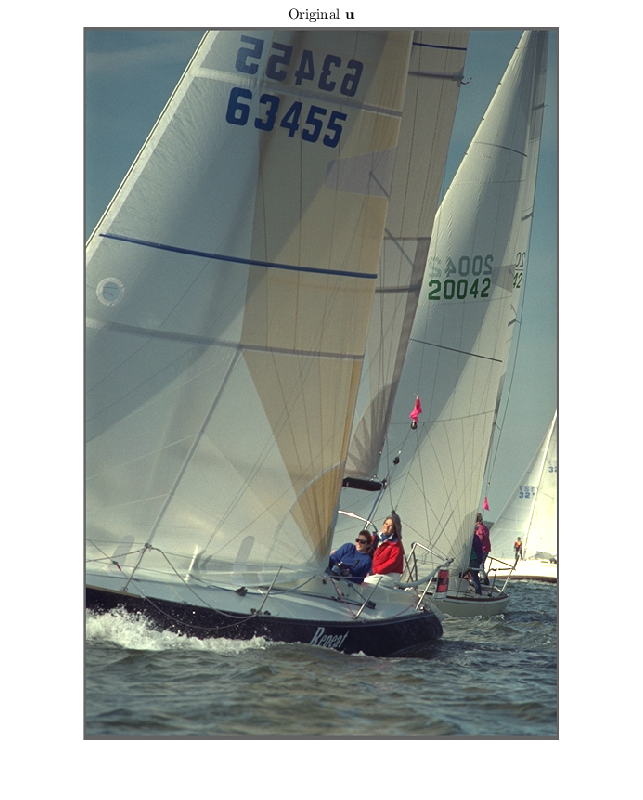

% Original image    datalink: https://r0k.us/graphics/kodak/
uSrc = imresize(im2single(imread('./data/kodim10.png')),1);
figure
imshow(uSrc)
title("Original $\mathbf{u}$","Interpreter","latex")

imgufile = './data/sdip_org.png';
imwrite(uSrc,imgufile)

## Bivariate lattice-structure oversampled filter banks 

As an example, let us adopt a non-separable oversampled lapped transform (NSOLT) of  type-I with the number of channels (the numbers of even and odd symmetric channels are identical to each other) and polyphase order (even):

        
$$\mathbf{E}(z_\mathrm{v},z_\mathbf{h})
=
\left(\prod_{k_\mathrm{h}=1}^{N_\mathrm{h}/2}
{\mathbf{V}_{2k_\mathrm{h}}^{\{\mathrm{h}\}}}\bar{\mathbf{Q}}(z_\mathrm{h}){\mathbf{V}_{2k_\mathrm{h}-1}^{\{\mathrm{h}\}}}{\mathbf{Q}}(z_\mathrm{h})\right)
%
\left(\prod_{k_{\mathrm{v}}=1}^{N_\mathrm{v}/2}{\mathbf{V}_{2k_\mathrm{v}}^{\{\mathrm{v}\}}}\bar{\mathbf{Q}}(z_\mathrm{v}){\mathbf{V}_{2k_\mathrm{v}-1}^{\{\mathrm{v}\}}}{\mathbf{Q}}(z_\mathrm{v})\right)
%
\mathbf{V}_0\mathbf{E}_0,$$


        
$$\mathbf{R}(z_\mathrm{v},z_\mathbf{h})
=\mathbf{E}^T(z_\mathrm{v}^{-1},z_\mathrm{h}^{-1}),$$


where

- $\mathbf{E}(z_\mathrm{v},z_\mathrm{h})$:  Type-I polyphase matrix of the analysis filter bank

- $\mathbf{R}(z_\mathrm{v},z_\mathrm{h})$: Type-II polyphase matrix in the synthesis filter bank

- $z_d\in\mathbb{C}, d\in\{\mathrm{v},\mathrm{h}\}$: The parameter of Z-transformation direction

- $N_d\in \mathbb{N}, d\in\{\mathrm{v},\mathrm{h}\}$: Polyphase order in direction $d$ (number of overlapping blocks)

- $\mathbf{V}_0=\left(\begin{array}{cc}\mathbf{W}_{0} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_0\end{array}\right)
%
\left(\begin{array}{c}\mathbf{I}_{M/2} \\ 
\mathbf{O} \\
\mathbf{I}_{M/2} \\
\mathbf{O}
\end{array}\right)\in\mathbb{R}^{P\times M}$,$\mathbf{V}_n^{\{d\}}=\left(\begin{array}{cc}\mathbf{I}_{P/2} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_n^{\{d\}}\end{array}\right)\in\mathbb{R}^{P\times P}, d\in\{\mathrm{v},\mathrm{h}\}$, where$\mathbf{W}_0, \mathbf{U}_0,\mathbf{U}_n^{\{d\}}\in\mathbb{R}^{P/2\times P/2}$are orthonromal matrices.

- $\mathbf{Q}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  z^{-1}\mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\bar{\mathbf{Q}}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} z\mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  \mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\mathbf{B}_{P}=\frac{1}{\sqrt{2}}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{I}_{P/2} \\ \mathbf{I}_{P/2} &  -\mathbf{I}_{P/2}\end{array}\right)$

【References】 

- MATLAB SaivDr Package: [https://github.com/msiplab/SaivDr](https://github.com/msiplab/SaivDr)

- S. Muramatsu, K. Furuya and N. Yuki, "Multidimensional Nonseparable Oversampled Lapped Transforms: Theory and Design," in IEEE Transactions on Signal Processing, vol. 65, no. 5, pp. 1251-1264, 1 March1, 2017, doi: 10.1109/TSP.2016.2633240.

- S. Muramatsu, T. Kobayashi, M. Hiki and H. Kikuchi, "Boundary Operation of 2-D Nonseparable Linear-Phase Paraunitary Filter Banks," in IEEE Transactions on Image Processing, vol. 21, no. 4, pp. 2314-2318, April 2012, doi: 10.1109/TIP.2011.2181527.

- S. Muramatsu, M. Ishii and Z. Chen, "Efficient parameter optimization for example-based design of nonseparable oversampled lapped transform," 2016 IEEE International Conference on Image Processing (ICIP), Phoenix, AZ, 2016, pp. 3618-3622, doi: 10.1109/ICIP.2016.7533034.

- Furuya, K., Hara, S., Seino, K., & Muramatsu, S. (2016). Boundary operation of 2D non-separable oversampled lapped transforms. *APSIPA Transactions on Signal and Information Processing, 5*, E9. doi:10.1017/ATSIP.2016.3.

- R. Kobayashi and S. Muramatsu, "Convolutional Nonlinear Dictionary with Cascaded Structure Filter Banks," 2020 IEEE International Conference on Consumer Electronics - Asia (ICCE-Asia), Seoul, Korea (South), 2020, pp. 1-4, doi: 10.1109/ICCE-Asia49877.2020.9277243.

isProfile = false

isProfile = logical
   0


checkInitialState = false

checkInitialState = logical
   0


## Hierachical decomposition for 2-D Grayscale image

Let $R_M^P(\tau)$ be the redundancy of $\tau$-level tree-structured filter bank, then we have the relation 

    
$$R_M^P(\tau)=\left\{\begin{array}{ll} (P-1)\tau + 1, & M=1, \\ \frac{P-1}{M-1}-\frac{P-M}{(M-1)M^\tau}, & M\geq 2.\end{array}\right.$$


% Decimation factor (Strides)
decFactor = [1 1] * 2 % [My Mx]

decFactor =      2     2



% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [1 1] * 6% [Ps Pa] (Ps=Pa)  3_4 27,32  4_12 27.68

nChannels =      6     6



% Number of tree levels
nLevels = 4%

nLevels = 4

P = sum(nChannels);
kernelsz = prod(decFactor);
redundancy = ...
    (prod(decFactor)==1)*((P-1)*nLevels+1) + ...
    (prod(decFactor)>1)*((P-1)/(kernelsz-1)-(P-kernelsz)/((kernelsz-1)*kernelsz^nLevels))

redundancy = 3.6563


% Polyphase Order 
ppOrder = [1 1] *4

ppOrder =      4     4


% No DC-leakage
noDcLeakageOfAnalyzer = true;
noDcLeakageOfSynthesizer = true;
noDcLeakage = [ noDcLeakageOfAnalyzer, noDcLeakageOfSynthesizer ]

noDcLeakage = 1×2 logical 数组
   1   1


% Standard deviation of initial angles
iscpparamsyn2ana = true  

iscpparamsyn2ana = logical
   1


stdInitAngAnalyzer = pi/6; 
stdInitAngSynthesizer = pi/6; 

% Initial learning rate
initialLearnRate = 20

initialLearnRate = 20


% Learn rate factors (Set factor to 0 for frozen parameters)
factor4angles = 10; % NSOLT
% factor4sigma = 10; % LET 
factor4a1 = 10; % LET
factor4a2 = 10; % LET
factor4a3 = 10; % LET
factor4a4 = 10; % LET
factor4Sigma_R = 0;%R

factor4sigma = 0; % LET1e-2
factor4a1_1 = 10; % LET
factor4a2_2 = 10; % LET
% L2 factors (Set factor to 0 for no regularization)
l2factor4angles = 10; % NSOLT
l2factor4a1 = 10; 
l2factor4a2 = 10; 
l2factor4a3 = 10; 
l2factor4a4 = 10; 
l2factor4Sigma_R = 0;


l2factor4sigma = 0; % LET1e-2
l2factor4a1_1 = 10; % LET
l2factor4a2_2 = 10; % LET
% Number of patchs per image
nSubImgs = 1; 

% Mini batch size
miniBatchSize = 1;

% Number of Epochs (1 Epoch = nSubImgs/miniBachSize iterlations)
maxEpochs = 2^8

maxEpochs = 256


if checkInitialState
    maxEpochs = 0*maxEpochs;
end

% Number of iterations
maxIters = nSubImgs/miniBatchSize * maxEpochs

maxIters = 256

% Patch size for training
% szPatchTrn = [128 128 3]; % > [ (Ny+1)My (Nx+1)Mx ]    
[x,y,z] = size(uSrc);
n=1;% Patch size
szPatchTrn = [x/n y/n z];
szPatchTrn2 = [x/n y/n];

Setting of dictionary update step


% Decay rate
decay = 0.001;

% Momentum
momentum = 0.9;

### Observed image

Let us consider the single image super resolution problem of observation:

    
$$\mathbf{v}=\mathbf{Pu}+\mathbf{w}$$


which originates  $\mathbf{u}$ and is contaminated by additive white Gaussian noise $\mathbf{w}$ and  $\mathbf{P}$ is a linear measurement process with identity operation

% Measurement process P
linproc = @(x) x;

% Observation
sigmaw = 40/255;
%sigmaw = 66/255;
disp(sigmaw)

    0.1569



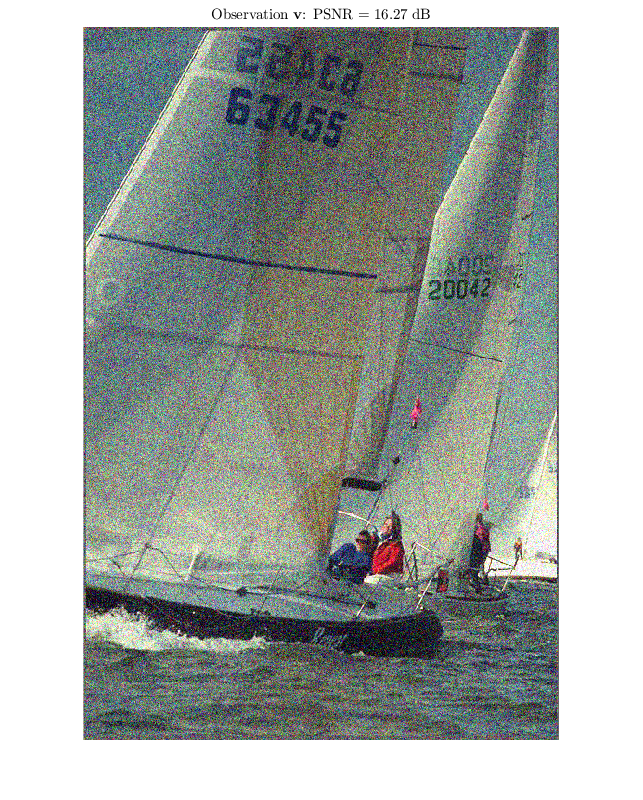

vObs = imnoise(linproc(uSrc),'gaussian',0,sigmaw^2);
figure
imshow(vObs)
title("Observation $\mathbf{v}$: PSNR = "+num2str(psnr(uSrc,vObs),'%6.2f') +" dB", ...
    "Interpreter","latex")

imgvfile = './data/sdip_obs.png';
imwrite(vObs,imgvfile);

## Robust estimator of noise variance $\sigma_\mathrm{w}^2$

### MAD estimator 

    
$$\hat{\sigma}=\frac{\mathrm{Median}\left(\left|Y_{i j}\right|\right)}{0.6745}, \quad Y_{i j} \in \text { subband } H H_{1} .$$


【References】 

- D. L. Donoho and I. M. Johnstone, "Adapting to unknown smoothness via wavelet shrinkage", *Journal of the American Statistical Assoc.*, vol. 90, no. 432, pp. 1200-1224, December 1995.

- S. G. Chang, Bin Yu and M. Vetterli, "Adaptive wavelet thresholding for image denoising and compression," in IEEE Transactions on Image Processing, vol. 9, no. 9, pp. 1532-1546, Sept. 2000, doi: 10.1109/83.862633.

% Noise variance estimation
%yhh = imfilter(imfilter(vObs,[1 -1]),[1;-1])/2;
%hatsigmaw = median(abs(yhh(:)))/0.6745;
%disp(hatsigmaw)

### Eigenfilter-based approach

    
$$\mathbf{h}_{\mathrm{opt}}=\arg \min _{\mathbf{h} \in \mathbb{R}^{M}}\|\mathbf{h} * \mathbf{y}\|^{2}\ \text { subject to }\ \|\mathbf{h}\|^{2}=1$$


    $\hat{\sigma}\leftarrow$ Estimated from the filtered residual ($\mathbf{h}_\mathrm{opt}\ast \mathbf{y}$),

as the mode of the smoothed histogram of the local noise variances computed inside blocks of given size (typically, $25\times 25$).

【References】 

- [https://scholar.harvard.edu/files/fluisier/files/icip10tutorial_part1.pdf](https://scholar.harvard.edu/files/fluisier/files/icip10tutorial_part1.pdf)

% get intercolor covariance matrix R
R_ = zeros(3,3); 
for c=1:3
    vObs1 = vObs(:,:,c);

blksz = [3 3]; % Filter kernel size
vblks = im2col(vObs1,blksz,'sliding'); % Sliding block data
Rvv = corrcoef(vblks.'); % Correlation matrix
[rv,rd] = eig(Rvv); % Eigenvalues and eigenvectors
[~,imin] = min(diag(rd)); % Index of minimum eigenvalue
hopt = reshape(rv(:,imin),blksz); % Filter kernel as eigenvector
yhh = imfilter(vObs1,double(hopt),'corr','symmetric'); % Filtering
figure
imshow(yhh+0.5)
drawnow

% The mode of the smoothed histogram of the local noise variances
yblks = im2col(yhh,[25 25],'sliding');
ystds = std(yblks,0,1);
figure
hystds = histogram(ystds);
title("Distribution of the Local Standard Deviations")
ax = hystds.Parent;
ax.XLim = hystds.BinLimits;
hold on
sigmas_ = double((hystds.BinEdges(1:end-1)+hystds.BinEdges(2:end))/2);
f = fit(sigmas_(:),hystds.Values(:),'smoothingspline');
[vmax,imax] = max(f(sigmas_(:)));
hatsigmaw_R = sigmas_(imax);
plot(f)
plot(hatsigmaw_R,vmax,'x')
hold off

clear Rvv rv rd hopt blksz vblks yhh ystds hystds ;% save memory
R_(c,c) = hatsigmaw_R;
% Estimated standard deviation of noise
disp(hatsigmaw_R) 
end

    0.1542



    0.1537



    0.1547



R_ = 255*R_;
R_ = R_^2 ;
R_ = inv(R_);
R =  R_  % intercolor covariance matrix R

R = 	1.0e+-3 *

    0.6464         0         0
         0    0.6506         0
         0         0    0.6422



blksz = [3 3]; % Filter kernel size
vblks = im2col(vObs,blksz,'sliding'); % Sliding block data
Rvv = corrcoef(vblks.'); % Correlation matrix
[rv,rd] = eig(Rvv); % Eigenvalues and eigenvectors
[~,imin] = min(diag(rd)); % Index of minimum eigenvalue
hopt = reshape(rv(:,imin),blksz); % Filter kernel as eigenvector
yhh = imfilter(vObs,double(hopt),'corr','symmetric'); % Filtering
figure
imshow(yhh+0.5)

drawnow
clear Rvv rv rd hopt blksz vblks hopt;
% The mode of the smoothed histogram of the local noise variances
yblks = im2col(yhh,[25 25],'sliding');
ystds = std(yblks,0,1);
figure
hystds = histogram(ystds);
title("Distribution of the Local Standard Deviations")
ax = hystds.Parent;
ax.XLim = hystds.BinLimits;
hold on
sigmas_ = double((hystds.BinEdges(1:end-1)+hystds.BinEdges(2:end))/2);
f = fit(sigmas_(:),hystds.Values(:),'smoothingspline');
[vmax,imax] = max(f(sigmas_(:)));
hatsigmaw = sigmas_(imax);
plot(f)
plot(hatsigmaw,vmax,'x')
hold off

% Estimated standard deviation of noise
disp(hatsigmaw) 

    0.1543



## Construction of layers

import saivdr.dcnn.*
nComponents = 3;

sdiplgraph = fcn_creatensoltlgraph2d([],...
    'InputSize',szPatchTrn2,...
    'NumberOfComponents',nComponents,...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NumberOfLevels',nLevels,...
    'NumberOfVanishingMoments',noDcLeakage);
analyzeNetwork(sdiplgraph)

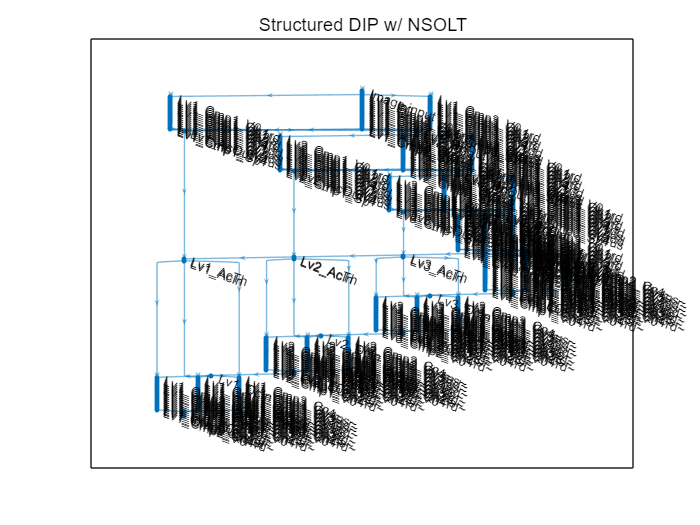


% Create structured DIP network with NSOLTs

% Analyzer
strLvPre = '';
for iLv = 1:nLevels
    strLv = sprintf('Lv%0d_',iLv);
    % Update
    strLvPre = strLv;
end

% Synthesizer
for iLv = nLevels:-1:1
    strLv = sprintf('Lv%0d_',iLv);
    sdiplgraph = sdiplgraph.disconnectLayers([strLv 'AcOut'],[strLv 'AcIn']);
    % For AC
    if iLv == nLevels
        sdiplgraph = sdiplgraph.addLayers(...
            letLayer_multichannel_Interchannel('Name',[strLv 'AcTh'], 'Sigma_R',R, ...
                'Sigma',hatsigmaw,... % Activation function for AC between Analyzer & Synthesizer
                'IsInterScale',false,...
                'NumberOfChannels',nComponents*(sum(nChannels)-1)));
        sdiplgraph = sdiplgraph.connectLayers([strLv 'AcOut'],[strLv 'AcTh']);
    else
        sdiplgraph = sdiplgraph.addLayers(...
            letLayer_multichannel_Interchannel('Name',[strLv 'AcTh'],'Sigma_R',R, ...
                'Sigma',hatsigmaw,... % Activation function for AC between Analyzer & Synthesizer
                'IsInterScale',true,...
                'NumberOfChannels',nComponents*(sum(nChannels)-1)));
        sdiplgraph = sdiplgraph.connectLayers([strLvPre 'AcTh'],[strLv 'AcTh/parent']);
        sdiplgraph = sdiplgraph.connectLayers([strLv 'AcOut'],[strLv 'AcTh/child']);
    end
    sdiplgraph = sdiplgraph.connectLayers([strLv 'AcTh'],[strLv 'AcIn']);
    strLvPre = strLv;
end

figure
plot(sdiplgraph)
title('Structured DIP w/ NSOLT')

## Random extraction of patches from the target image

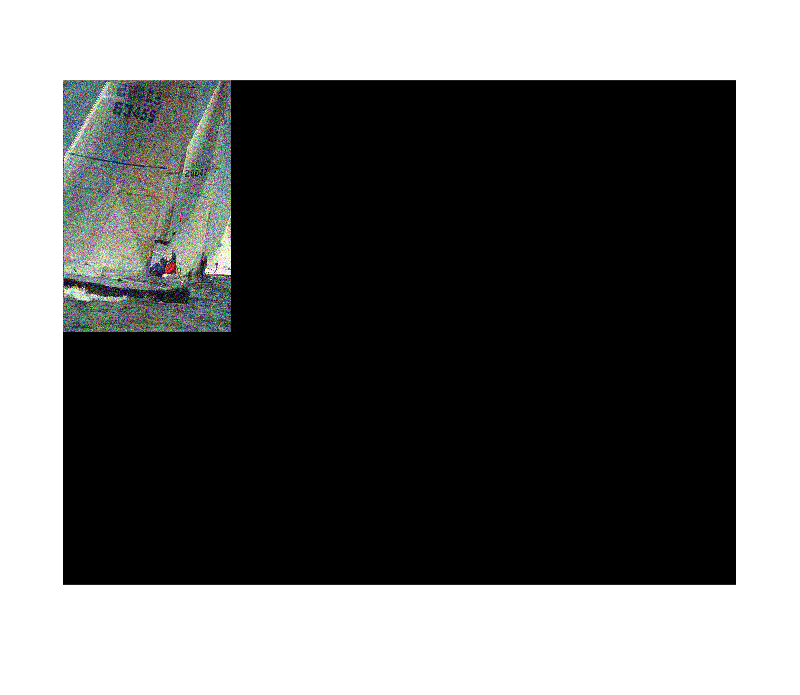

% Observation 
imdsv = imageDatastore(imgvfile,"ReadFcn",@(x) im2single(imread(x)));
% Original
imdsu = imageDatastore(imgufile,"ReadFcn",@(x) im2single(imread(x)));
% Patches for training
patchds = randomPatchExtractionDatastore(imdsv,imdsv,szPatchTrn,'PatchesPerImage',nSubImgs); % DIP
figure
minibatch = preview(patchds);
inputimg = minibatch.InputImage;
montage(inputimg,'Size',[2 4]);

figure
responses = minibatch.ResponseImage;
montage(responses,'Size',[2 4]);

## Structured DIP wth SURE

### Problem setting:

    
$$\hat{\mathbf{\theta}}=\arg\min_{\mathbf{\theta}}\frac{1}{S}\sum_{n=1}^{S}\left(\frac{1}{N}\|\mathbf{F}(\mathbf{v}_n)-\mathbf{v}_n\|_2^2+\frac{2\sigma_\mathrm{w}^2}{N}\mathrm{div}\{\mathbf{F}(\mathbf{v}_n)\}-\sigma_\mathrm{w}^2\right),$$


where $\mathbf{T}_{\theta}$  and $\mathbf{D}_{\theta}$ are an analysis and synthesis convolutional dictionary with the design parameters, and

    $\mathbf{F}(\mathbf{x})=\mathbf{D}_{\theta_s}\phi_{\theta_f}\left(\mathbf{T}_{\theta_a}\mathbf{x}\right)$.

### Preparation for training

% Analyze network 
analyzeNetwork(sdiplgraph)

% Construction of deep learning network.
trainlgraph = sdiplgraph.removeLayers('Image output');
dlX = dlarray(vObs,"SSCB");
sdipnet = dlnetwork(trainlgraph,dlX);


% Initialize parameters
expanalyzer = '^Lv\d+_\w*V(\w\d|0)+$';
expsynthesizer = '^Lv\d+_\w*V(\w\d|0)+~$';
nLearnables = height(sdipnet.Learnables);
for iLearnable = 1:nLearnables
    if sdipnet.Learnables.Parameter(iLearnable)=="Angles"
        layerName = sdipnet.Learnables.Layer(iLearnable);
        if ~isempty(regexp(layerName,expanalyzer,'once'))
            stdInitAng = stdInitAngAnalyzer;
        elseif ~isempty(regexp(layerName,expsynthesizer,'once'))
            stdInitAng = stdInitAngSynthesizer;
        else
            error("Invalid learnable angles exist in " + layerName + ".")
        end
        sdipnet.Learnables.Value(iLearnable) = ...
            cellfun(@(x) x+stdInitAng*randn(size(x)), ...
            sdipnet.Learnables.Value(iLearnable),'UniformOutput',false);
    end
end

% Copy parameters from synthesizer to analyzer
if iscpparamsyn2ana
    sdipnet = fcn_cpparamssyn2ana_(sdipnet);
end

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv1_Cmp2_V0~ to Lv1_Cmp2_V0
Copy angles from Lv1_Cmp2_Vh1~ to Lv1_Cmp2_Vh1
Copy angles from Lv1_Cmp2_Vh2~ to Lv1_Cmp2_Vh2
Copy angles from Lv1_Cmp2_Vh3~ to Lv1_Cmp2_Vh3
Copy angles from Lv1_Cmp2_Vh4~ to Lv1_Cmp2_Vh4
Copy angles from Lv1_Cmp2_Vv1~ to Lv1_Cmp2_Vv1
Copy angles from Lv1_Cmp2_Vv2~ to Lv1_Cmp2_Vv2
Copy angles from Lv1_Cmp2_Vv3~ to Lv1_Cmp2_Vv3
Copy angles from Lv1_Cmp2_Vv4~ to Lv1_Cmp2_Vv4
Copy angles from Lv1_Cmp3_V0~ to Lv1_Cmp3_V0
Copy angles from Lv1_Cmp3_Vh1~ to Lv1_Cmp3_Vh1
Copy angles from Lv1_Cmp3_Vh2~ to Lv1_Cmp3_Vh2
Copy angles from Lv


% Set learn rate factor & L2 factor
expacout = '^Lv\d+_\w*AcOut$';
expdcout = '^Lv\d+_\w*DcOut$';
for iLearnable = 1:nLearnables
    layerName = sdipnet.Learnables.Layer(iLearnable);
    parameterName = sdipnet.Learnables.Parameter(iLearnable);
    if parameterName == "Angles"
        sdipnet = sdipnet.setLearnRateFactor(layerName,"Angles",factor4angles);
        sdipnet = sdipnet.setL2Factor(layerName,"Angles",l2factor4angles);
    % elseif parameterName == "Sigma"
    %     sdipnet = sdipnet.setLearnRateFactor(layerName,"Sigma",factor4sigma);
    %     sdipnet = sdipnet.setL2Factor(layerName,"Sigma",l2factor4sigma);
    elseif parameterName == "Sigma_R"
         sdipnet = sdipnet.setLearnRateFactor(layerName,"Sigma_R",factor4Sigma_R);
         sdipnet = sdipnet.setL2Factor(layerName,"Sigma_R",l2factor4Sigma_R);

    elseif parameterName == "Sigma"
        sdipnet = sdipnet.setLearnRateFactor(layerName,"Sigma",factor4sigma);
        sdipnet = sdipnet.setL2Factor(layerName,"Sigma",l2factor4sigma);
    elseif parameterName == "a1_1"
        sdipnet = sdipnet.setLearnRateFactor(layerName,"a1_1",factor4a1_1); 
        sdipnet = sdipnet.setL2Factor(layerName,"a1_1",l2factor4a1_1);
    elseif parameterName == "a2_2"
        sdipnet = sdipnet.setLearnRateFactor(layerName,"a2",factor4a2_2);
        sdipnet = sdipnet.setL2Factor(layerName,"a2",l2factor4a2_2);


    elseif parameterName == "a1"
        sdipnet = sdipnet.setLearnRateFactor(layerName,"a1",factor4a1); 
        sdipnet = sdipnet.setL2Factor(layerName,"a1",l2factor4a1);
    elseif parameterName == "a2"
        sdipnet = sdipnet.setLearnRateFactor(layerName,"a2",factor4a2);
        sdipnet = sdipnet.setL2Factor(layerName,"a2",l2factor4a2);
    elseif parameterName == "a3"
        sdipnet = sdipnet.setLearnRateFactor(layerName,"a3",factor4a3);
        sdipnet = sdipnet.setL2Factor(layerName,"a3",l2factor4a3);
    elseif parameterName == "a4"
        sdipnet = sdipnet.setLearnRateFactor(layerName,"a4",factor4a4);
        sdipnet = sdipnet.setL2Factor(layerName,"a4",l2factor4a4);
    end
end

Learn rate factor

nParams = 0;
for iLearnable = 1:nLearnables
    layerName = sdipnet.Learnables.Layer(iLearnable);
    parameterName = sdipnet.Learnables.Parameter(iLearnable);
    learnRateFactor = sdipnet.getLearnRateFactor(layerName,parameterName);
    disp(parameterName + "@" + layerName + ": " + learnRateFactor);
    if learnRateFactor > 0
        value = sdipnet.Learnables.Value(iLearnable);
        nParams = nParams + numel(value{1});
    end
end

Angles@Lv1_Cmp1_V0: 10
Angles@Lv1_Cmp1_Vh1: 10
Angles@Lv1_Cmp1_Vh2: 10
Angles@Lv1_Cmp1_Vh3: 10
Angles@Lv1_Cmp1_Vh4: 10
Angles@Lv1_Cmp1_Vv1: 10
Angles@Lv1_Cmp1_Vv2: 10
Angles@Lv1_Cmp1_Vv3: 10
Angles@Lv1_Cmp1_Vv4: 10
Angles@Lv1_Cmp2_V0: 10
Angles@Lv1_Cmp2_Vh1: 10
Angles@Lv1_Cmp2_Vh2: 10
Angles@Lv1_Cmp2_Vh3: 10
Angles@Lv1_Cmp2_Vh4: 10
Angles@Lv1_Cmp2_Vv1: 10
Angles@Lv1_Cmp2_Vv2: 10
Angles@Lv1_Cmp2_Vv3: 10
Angles@Lv1_Cmp2_Vv4: 10
Angles@Lv1_Cmp3_V0: 10
Angles@Lv1_Cmp3_Vh1: 10
Angles@Lv1_Cmp3_Vh2: 10
Angles@Lv1_Cmp3_Vh3: 10
Angles@Lv1_Cmp3_Vh4: 10
Angles@Lv1_Cmp3_Vv1: 10
Angles@Lv1_Cmp3_Vv2: 10
Angles@Lv1_Cmp3_Vv3: 10
Angles@Lv1_Cmp3_Vv4: 10
Angles@Lv2_Cmp1_V0: 10
Angles@Lv2_Cmp1_Vh1: 10
Angles@Lv2_Cmp1_Vh2: 10
Angles@Lv2_Cmp1_Vh3: 10
Angles@Lv2_Cmp1_Vh4: 10
Angles@Lv2_Cmp1_Vv1: 10
Angles@Lv2_Cmp1_Vv2: 10
Angles@Lv2_Cmp1_Vv3: 10
Angles@Lv2_Cmp1_Vv4: 10
Angles@Lv2_Cmp2_V0: 10
Angles@Lv2_Cmp2_Vh1: 10
Angles@Lv2_Cmp2_Vh2: 10
Angles@Lv2_Cmp2_Vh3: 10
Angles@Lv2_Cmp2_Vh4: 10
Angles@Lv2_Cmp2_Vv1: 

disp("# of Parameters: = " + nParams)

# of Parameters: = 5448


NOTE: The above number excludes frozen parameters, whose learn rate factors are set to zero.

L2 factor

for iLearnable = 1:nLearnables
    layerName = sdipnet.Learnables.Layer(iLearnable);
    parameterName = sdipnet.Learnables.Parameter(iLearnable);
    disp(parameterName + "@" + layerName + ": " + sdipnet.getL2Factor(layerName,parameterName))
end

Angles@Lv1_Cmp1_V0: 10
Angles@Lv1_Cmp1_Vh1: 10
Angles@Lv1_Cmp1_Vh2: 10
Angles@Lv1_Cmp1_Vh3: 10
Angles@Lv1_Cmp1_Vh4: 10
Angles@Lv1_Cmp1_Vv1: 10
Angles@Lv1_Cmp1_Vv2: 10
Angles@Lv1_Cmp1_Vv3: 10
Angles@Lv1_Cmp1_Vv4: 10
Angles@Lv1_Cmp2_V0: 10
Angles@Lv1_Cmp2_Vh1: 10
Angles@Lv1_Cmp2_Vh2: 10
Angles@Lv1_Cmp2_Vh3: 10
Angles@Lv1_Cmp2_Vh4: 10
Angles@Lv1_Cmp2_Vv1: 10
Angles@Lv1_Cmp2_Vv2: 10
Angles@Lv1_Cmp2_Vv3: 10
Angles@Lv1_Cmp2_Vv4: 10
Angles@Lv1_Cmp3_V0: 10
Angles@Lv1_Cmp3_Vh1: 10
Angles@Lv1_Cmp3_Vh2: 10
Angles@Lv1_Cmp3_Vh3: 10
Angles@Lv1_Cmp3_Vh4: 10
Angles@Lv1_Cmp3_Vv1: 10
Angles@Lv1_Cmp3_Vv2: 10
Angles@Lv1_Cmp3_Vv3: 10
Angles@Lv1_Cmp3_Vv4: 10
Angles@Lv2_Cmp1_V0: 10
Angles@Lv2_Cmp1_Vh1: 10
Angles@Lv2_Cmp1_Vh2: 10
Angles@Lv2_Cmp1_Vh3: 10
Angles@Lv2_Cmp1_Vh4: 10
Angles@Lv2_Cmp1_Vv1: 10
Angles@Lv2_Cmp1_Vv2: 10
Angles@Lv2_Cmp1_Vv3: 10
Angles@Lv2_Cmp1_Vv4: 10
Angles@Lv2_Cmp2_V0: 10
Angles@Lv2_Cmp2_Vh1: 10
Angles@Lv2_Cmp2_Vh2: 10
Angles@Lv2_Cmp2_Vh3: 10
Angles@Lv2_Cmp2_Vh4: 10
Angles@Lv2_Cmp2_Vv1: 

## Training

sdipnet.Initialized

ans = logical
   1


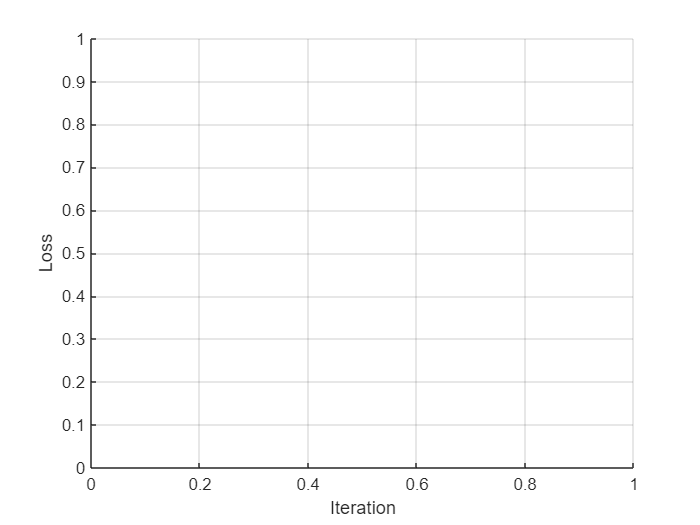

mbq = minibatchqueue(patchds,...
    'MiniBatchSize',miniBatchSize,...
    'MiniBatchFormat',{'SSCB','SSCB'});
figure
lineLossTrain = animatedline('Color',[0.85 0.325 0.098]);
ylim([0 inf])
xlabel("Iteration")
ylabel("Loss")
grid on

if isProfile
    profile off
    profile on
end

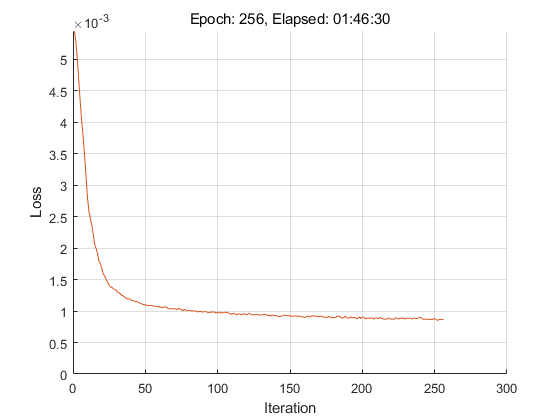


% Training
%sdipdagnet = trainNetwork(patchds,trainlgraph,opts);
velocity = [];
iteration = 0;
start = tic;

% Loop over epochs.
for epoch = 1:maxEpochs
    % Shuffle data.
    shuffle(mbq);
    
    % Loop over mini-batches.
    while hasdata(mbq)
        iteration = iteration + 1;
        
        % Read mini-batch of data.
        [dlX, T] = next(mbq);
        
        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelGradients function and update the network state.
        [gradients,loss] = dlfeval(@modelGradients,sdipnet,dlX,T,hatsigmaw);

        % Determine learning rate for time-based decay learning rate schedule.
        learnRate = initialLearnRate/(1 + decay*iteration);
        
        % Update the network parameters using the SGDM optimizer.
        [sdipnet,velocity] = sgdmupdate(sdipnet,gradients,velocity,learnRate,momentum);
        
        % Display the training progress.
        D = duration(0,0,toc(start),'Format','hh:mm:ss');
        addpoints(lineLossTrain,iteration,loss)
        title("Epoch: " + epoch + ", Elapsed: " + string(D))
        drawnow
    end
end

if isProfile
    profile off
    profile viewer
end

## Restoration from observation

    
$$\hat{\mathbf{y}}=\mathbf{D}_{\hat{\theta}_s}\phi_{\hat{\theta}_f}\left(\mathbf{T}_{\hat{\theta}_a}\mathbf{v}\right)$$


sdiplgraph = layerGraph(sdipnet); 
sdiplgraph = sdiplgraph.replaceLayer('Image input',...
        imageInputLayer(size(vObs),'Name','Image input','Normalization','none'));

% Construction of deep learning network.
sdipnet = dlnetwork(sdiplgraph);

% Observation
dlv = dlarray(vObs,'SSC');
dly = sdipnet.predict(dlv);

uRst = extractdata(dly);

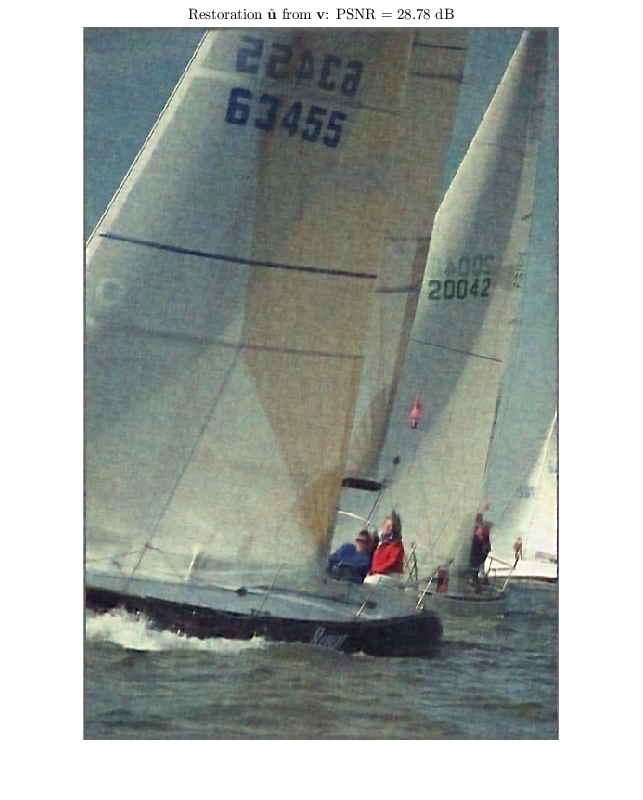

figure
imshow(uRst)
title("Restoration $\hat{\mathbf{u}}$ from $\mathbf{v}$: PSNR = "+ num2str(psnr(uSrc,uRst),'%6.2f') +" dB", ...
    "Interpreter","latex"); 

imwrite(uRst,'./data/ko_sdip_rsy_mul.png') 
imwrite(uRst,'C:\Users\ljkyj\Desktop\ITE_journal\30_255\k09_sdip_rsy_mul.png') 

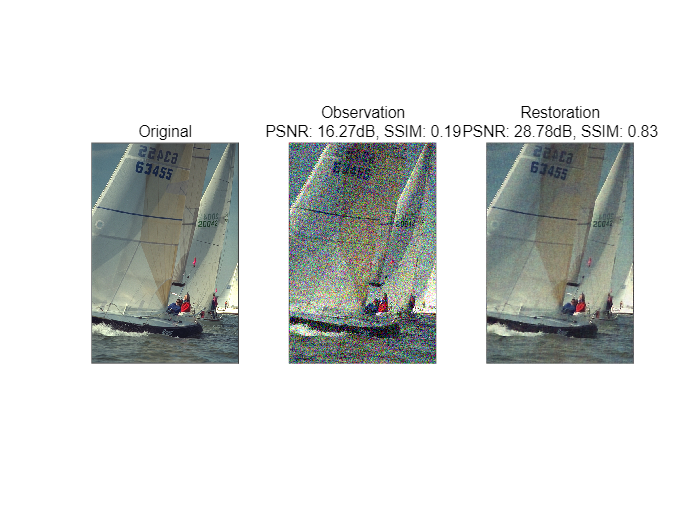


figure
tiledlayout(1,3)
nexttile
imshow(uSrc)
title("Original")
nexttile
imshow(vObs)
title("Observation"+newline + ...
    "PSNR: "+num2str(psnr(uSrc,vObs),'%6.2f') + "dB, SSIM: "+ num2str(ssim(uSrc,vObs), '%5.2f'))
nexttile
imshow(uRst)
title("Restoration"+newline+ ...
    "PSNR: "+num2str(psnr(uSrc,uRst),'%6.2f') + "dB, SSIM: "+ num2str(ssim(uSrc,uRst), '%5.2f')) 

## Gradients

Loss function (SURE)

    $L(\mathbf{\theta})=\frac{1}{N}\|\mathbf{F}_{\mathbf{\theta}}(\mathbf{v})-\mathbf{v}\|_2^2+\frac{2\sigma_\mathrm{w}^2}{N}\mathrm{div}\{\mathbf{F}_{\mathbf{\theta}}(\mathbf{v})\}-\sigma_\mathrm{w}^2$.

The following Monte-Calro divergence estimation was adopted in the original:

    $\mathrm{div}\{\mathbf{F}(\mathbf{x})\}=\sum_{n=1}^{N}\frac{\partial F_n(\mathbf{x})}{\partial x_n}\simeq \mathbf{b}_0^T\frac{\mathbf{F}(\mathbf{x}+\varepsilon\mathbf{b}_0)-\mathbf{F}(\mathbf{x})}{\varepsilon}$,

where $\varepsilon=\sigma_\mathrm{w}/100$ and $\mathbf{b}_0\sim \mathcal{N}(\mathbf{0},\mathbf{1})$.

【References】 

- [https://scholar.harvard.edu/files/fluisier/files/icip10tutorial_part1.pdf](https://scholar.harvard.edu/files/fluisier/files/icip10tutorial_part1.pdf)

- [https://jp.mathworks.com/help/deeplearning/ug/define-custom-deep-learning-output-layers.html](https://jp.mathworks.com/help/deeplearning/ug/define-custom-deep-learning-output-layers.html)

- [https://jp.mathworks.com/help/deeplearning/ug/define-model-gradients-function-for-custom-training-loop.html](https://jp.mathworks.com/help/deeplearning/ug/define-model-gradients-function-for-custom-training-loop.html)

function [gradients, loss] = modelGradients(dlnet, dlX, T, sigmaw)
    % Forward data through the dlnetwork object.
    dlY0 = forward(dlnet,dlX); % F(v)
        
    % MC divergence estimation
    b0_ = randn(size(dlX),'like',dlX); % b0~Norm(0,1)
    eps_ = sigmaw/100; % ε=σ/100 
    dlY1 = forward(dlnet,dlX + eps_*b0_); % F(v+εb0)
    divF_N = mean(b0_.*(dlY1-dlY0),"all")/eps_; % div{F(v)}/N

    % Compute loss. 
    mse_ = mean((dlY0-T).^2,"all");
    div_ = 2*sigmaw^2*divF_N;
    sure = mse_ + div_ - sigmaw^2; % SURE

    % Compute gradients.
    gradients = dlgradient(sure,dlnet.Learnables);

    loss = double(gather(extractdata(sure)));
end

function nsoltnet = fcn_cpparamssyn2ana_(nsoltnet)
%FCN_CPPARAMSSYN2ANA_
%
% Setting up the analysis dictionary (adjoint operator) by copying
% synthesis dictionary parameters to the analyisis dictionary
%
import saivdr.dcnn.*
%
lgraph = layerGraph(nsoltnet);

expanalyzer = '^Lv\d+_Cmp\d+_V(\w\d|0)+$';
nLayers = height(lgraph.Layers);
for iLayer = 1:nLayers
    alayer = lgraph.Layers(iLayer);
    alayerName = alayer.Name;
    if ~isempty(regexp(alayerName,expanalyzer,'once'))
        slayer = lgraph.Layers({lgraph.Layers.Name} == alayerName + "~");
        alayer.Angles = slayer.Angles;
        alayer.Mus = slayer.Mus;
        if isa(alayer,'saivdr.dcnn.nsoltInitialRotation2dLayer')
            alayer.NoDcLeakage = slayer.NoDcLeakage;
        end
        lgraph = lgraph.replaceLayer(alayerName,alayer);
        disp("Copy angles from " + slayer.Name + " to " + alayerName)
    end
end
nsoltnet = dlnetwork(lgraph);
end

© Copyright, LI Jikai and Shogo MURAMATSU, All rights reserved.